## Qr Algorithm

the QR algorithm is a very impoprtant algorthm that allows us to find a Schur decomposition of a given matrix A, and consequently we can find the eigenvalue.

We will give a series of implementation of this problem.

### Simple QR Algorithm:

In this implementation we will see the easisest way to implement this algorithm, that is in a series of product using the result of the **QR decomposition algorithm**

format short
%Normal QR algorithm
A = Generate_Large_Matrix(4);
tic
A = Normal_QR(A,100);
toc

Elapsed time is 0.004741 seconds.


A

A =     4.0000   -1.3234    1.6547  -12.5005
    0.0000    3.0000   -1.6922   -2.3518
   -0.0000    0.0000    2.0000    2.0440
   -0.0000    0.0000    0.0000    1.0000


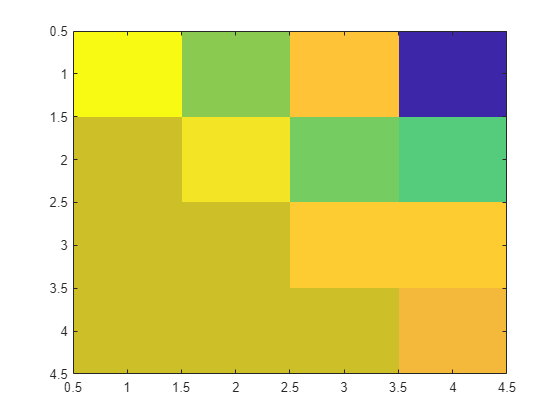

imagesc(A)

This implementation is slow in convergence and it requires a loat of iteration for the computation of the **QR decomposition, **we can try to speed this up

### Hessenberg Reduction

Using as imput a matrix in the Hessenber form we can reduce the time it takes to compute the QR algorithm.

%Hessemberg QR
A = Generate_Large_Matrix(5);
H = Hessenberg_reduction(A);
tic
H = Normal_QR(H, 500);
toc

Elapsed time is 0.004257 seconds.


H

H =     5.0000    0.3749    1.8303   -1.3480   -1.7631
    0.0000    4.0000    0.5593    1.2321    2.0983
         0    0.0000    3.0000   -0.2475   -1.0805
         0         0    0.0000    2.0000    0.1198
         0         0         0   -0.0000    1.0000


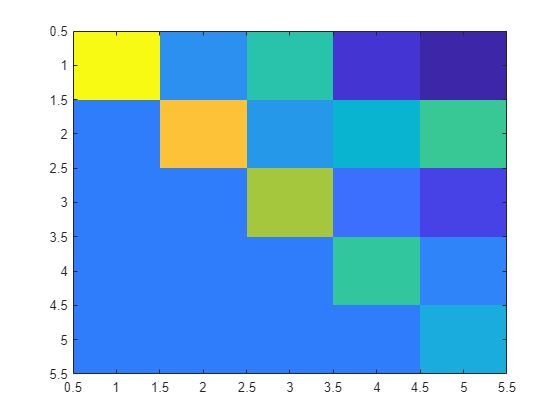

imagesc(H)

In the previou section we still used the basic QR Algorithm, now we will try to incorporate the givens rotation to annichilate the element under the main diagonal during the QR step.

A = Generate_Large_Matrix(6);
A = Hessenberg_reduction(A);
tic
A = Unshifted_QR(A,50);
toc

Elapsed time is 0.006023 seconds.


A

A =     6.0000   -0.3791   -1.4804   -0.1838    1.6473  -35.8093
    0.0000    5.0000   -0.0319    0.2116    2.7090  -18.0779
         0    0.0002    4.0000    0.6521   -5.8097   13.5616
         0         0    0.0000    3.0000   -0.9580    6.0549
         0         0         0    0.0000    2.0000   -4.4360
         0         0         0         0    0.0000    1.0000


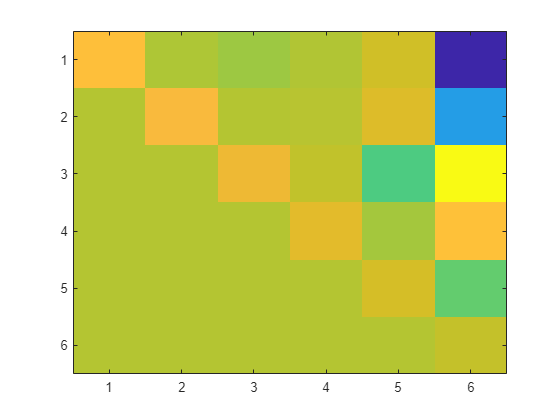

imagesc(A)

### Shift and deflation

we can still speed up this by incorporating some spectral shift with a deflation step

%Shifted QR factorization
%Real numbers
A = Generate_Large_Matrix(9);
H = Hessenberg_reduction(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.002474 seconds.


H

H =     1.0000    0.2748    6.4979    6.3901    0.0684   -5.6577   -4.7738  -14.6866  -12.3465
         0    2.0000    1.4925    5.8234   -0.4205   -2.3308   -3.2370   -2.9385   -0.1795
         0         0    9.0000    0.6369    1.0361   -0.8991   -0.3892   -0.9902   -3.4192
         0         0         0    8.0000   -0.8274   -0.2599   -4.5943    0.1367    7.8423
         0         0         0         0    3.0000    0.1365    0.1879   -3.3836    2.6551
         0         0         0         0         0    7.0000   -1.7004    0.4593    4.2363
         0         0         0         0         0         0    4.0000    1.5844    0.7914
         0         0         0         0         0         0         0    6.0000    0.1705
         0         0         0         0         0         0         0         0    5.0000


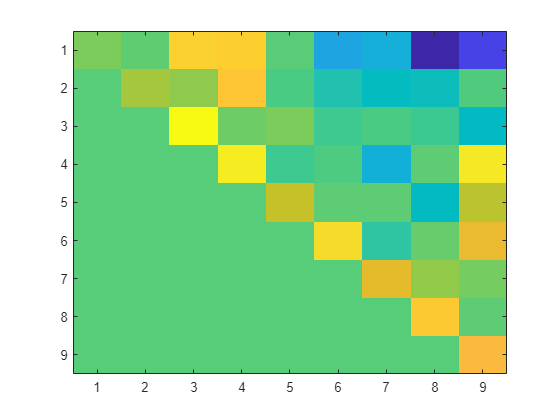

imagesc(H)

And with complex numbers

%Shifted QR factorization
%Complex numbers
N = 8;
cMatrix = complex(rand(N, N), rand(N,N));
idx = randperm(N,3);
cMatrix(idx(1),:) = cMatrix(idx(2),:) + rand * cMatrix(idx(3),:);
rank(cMatrix)

ans = 7

H = Hessenberg_reduction(cMatrix);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.003205 seconds.


H

H =    0.7813 + 1.3215i   0.0195 + 0.0207i  -0.0426 + 0.8112i   0.2916 + 0.0822i  -0.1885 - 0.1330i   0.0330 - 0.1068i  -0.0045 - 0.1184i   0.0350 - 0.0949i
   0.0000 + 0.0000i   0.7611 - 0.0017i  -0.0496 + 0.2615i   0.0639 - 0.0579i  -0.2052 - 0.1026i  -0.1224 + 0.1044i  -0.0152 - 0.0443i   0.0388 - 0.0030i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.4885 + 0.3132i  -0.1185 + 0.2435i  -0.0391 + 0.0842i  -0.0095 + 0.0299i   0.0165 - 0.0300i   0.0312 + 0.0063i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0453 - 0.3344i  -0.0341 - 0.0572i  -0.0409 - 0.0294i   0.0293 - 0.0145i   0.0214 - 0.0346i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1220 + 0.0909i   0.0409 + 0.0245i  -0.0241 + 0.0325i  -0.0372 - 0.0047i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0277 - 0.0295i  -0.0002 + 0.0146i  -0.0133 + 0.0030i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

Householder hessenberg

A = Generate_Large_Matrix(9);
H = householder_hessenberg(A);
tic
H = CHASE_THE_BULGE(H);
toc

Elapsed time is 0.004141 seconds.


H

H =     1.2871    1.3696   -2.9767    1.6532    0.6717   -1.3996    4.0257  -16.5841  -44.1743
    1.6170    8.7129   -0.5569   -2.1830    0.6571    6.9440   -3.7390   59.8978  164.3022
         0         0    8.0000   -3.8094    0.5234    6.7395   -4.1271   45.9751  130.2098
    0.0000    0.0000         0    2.0000    0.5161   -0.2166   -0.5117    2.3212   11.3308
    0.0000    0.0000   -0.0000         0    7.0062    3.6608   -1.0612   26.6002   72.9452
   -0.0000   -0.0000   -0.0000         0   -0.0068    2.9938   -0.3631   -9.6289  -24.6241
   -0.0000   -0.0000    0.0000    0.0000    0.0000         0    5.3068    5.1366   12.3501
   -0.0000   -0.0000         0    0.0000   -0.0000         0    0.1764    4.6932   -1.2484
    0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000         0    5.0000


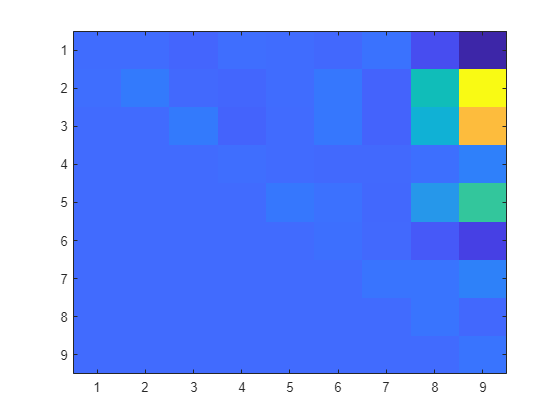

imagesc(H)

## Test Con matrici "Grandi"

A = Generate_Large_Matrix(50);
tic
A = Normal_QR(A,500);
toc

Elapsed time is 0.198109 seconds.


A

A =    49.9999    0.2009   -0.1059   -1.0333    0.3430   -0.6997   -0.3634   -0.1543   -2.1596    1.0728   -0.3376    1.8837   -1.6218    4.6746   -1.9404   -3.0315   -2.2452    1.2009    4.6369   -6.8592    6.4407   -0.9185    9.5137    1.1073    1.8748   -6.4536   -7.6637   -1.9879  -12.9158   -5.9373    2.5151   -8.3063   18.3037    5.3771   19.0816   -2.5219    2.9707    6.4236   18.5776    7.4428   21.9592  -12.9594  -13.6691   32.7515   -9.7464    5.7458  -26.1928   23.9191  164.2681  266.2856
    0.0007   49.0001    0.0729   -0.3250    0.2488    0.3915    0.2661   -0.7750   -0.1349    2.2199   -0.1615   -0.5799    0.0260   -0.3814    4.2380    1.6401   -0.0637    1.0409   -2.0670   -0.4024    0.1507    1.1054   -2.8674  -10.7042    1.2052    0.5031    6.4155    3.7235   -7.5572   -8.9176   -2.9956    4.4242    1.3763   13.0467    0.4407  -14.1456    6.7807   15.8371  -14.7723    6.5947   -2.3710   -0.2813    6.7005   18.0140   18.0108   39.4767    1.2406   -8.7685  107.8883  -41

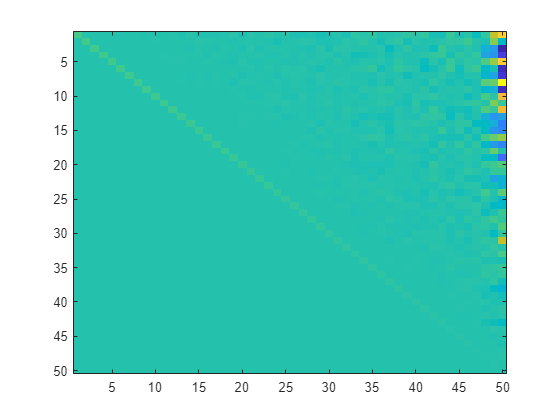

imagesc(A)

A = Generate_Large_Matrix(50);
H = Hessenberg_reduction(A);
tic
H = Unshifted_QR(H,1000);
toc

Elapsed time is 0.311406 seconds.


disp(H);

  Columns 1 through 21

   50.0000    0.0641   -0.2556    0.0689   -1.1521   -0.5957   -0.2287   -0.1667    1.3748   -1.2634   -0.8407    1.0045   -1.5981   -3.5698   -0.3876   -0.8379   -0.9909    3.3888   -4.9544   -5.7107   -2.0028
    0.0000   49.0000    0.1844   -0.1781    0.0864   -0.0892   -0.8011    2.0592   -0.9818   -0.2745   -1.5286   -0.6379   -2.7665    0.1718    4.3857   -2.1679   -0.6317   -0.6852   -4.0479   -0.1710   -5.7605
   -0.0000    0.0000   48.0000    0.0594    0.3045   -0.4422    0.2726   -0.2161   -0.2793   -1.1131    0.3647   -0.3504   -2.5155    1.7792    0.6982   -0.8669   -0.5274    0.9724    0.4760   -1.5061   -5.3205
   -0.0000   -0.0000    0.0000   47.0000   -0.1025   -0.6667    0.1485    0.2434   -2.0012   -1.2203    0.8542    3.1002   -1.7828   -1.1238   -4.0449   -1.3840   -0.9958   -2.3269   -3.6981    0.2215   -0.8443
   -0.0000    0.0000   -0.0000    0.0000   46.0000    0.1789   -0.1917   -0.3362    0.3935    0.3255    0.9607    1.3180    0.7608  

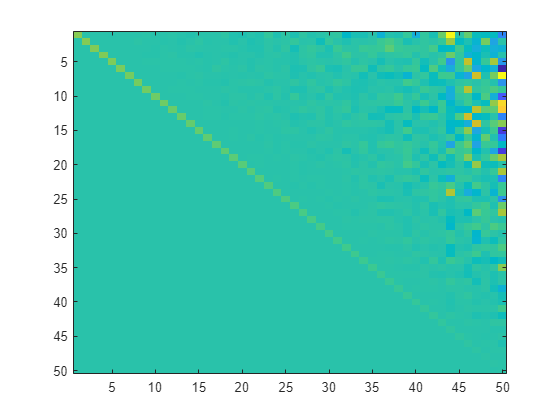

imagesc(H)

A = Generate_Large_Matrix(50);
H = Hessenberg_reduction(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.032629 seconds.


H

H = 1.0e+03 *

    0.0010   -0.0067   -0.0007   -0.0112   -0.0002   -0.0058   -0.0024   -0.0021   -0.0045    0.0051   -0.0030    0.0020    0.0020   -0.0079    0.0027    0.0039    0.0022   -0.0038   -0.0018   -0.0005   -0.0219    0.0072   -0.0072   -0.0078    0.0038    0.0087   -0.0015    0.0027   -0.0005    0.0122    0.0073    0.0092   -0.0051   -0.0025    0.0077   -0.0112    0.0138    0.0318   -0.0326    0.0519   -0.0314   -0.0641   -0.0025   -0.0174   -0.0101    0.0447   -0.0079   -0.1232   -1.1883    0.0578
         0    0.0500    0.0034    0.0004    0.0015   -0.0003    0.0010   -0.0087    0.0002   -0.0112   -0.0004    0.0158   -0.0065   -0.0038    0.0002    0.0196    0.0141    0.0061    0.0057    0.0054    0.0049   -0.0075   -0.0012    0.0095    0.0008    0.0122    0.0160   -0.0007   -0.0125   -0.0037   -0.0189    0.0108    0.0011    0.0088   -0.0430   -0.0339   -0.0092    0.0139   -0.0014   -0.0414   -0.0170    0.0424   -0.0361    0.0488    0.0290   -0.0070   -0.0272    0.0727    

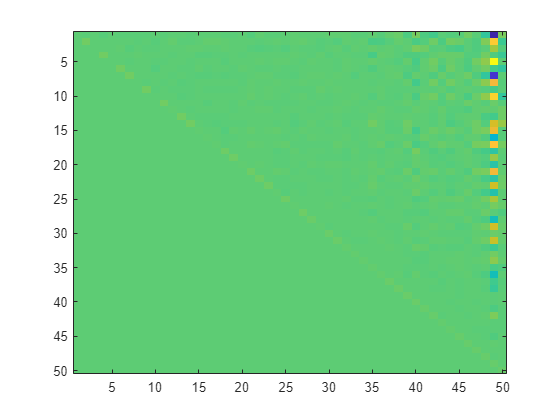

imagesc(H)

## Implementazioni:

### Simple QR

function A = Normal_QR(A, max_iter)
    for i=1:max_iter
        [Q,R] = mgs(A);
        A = R*Q;
    end
end

### Hessenberg Reduction

function A = Hessenberg_reduction(A)
    [num_rows, num_cols] = size(A);
    %itero sugli indici appena trovati
    for col=1:num_cols-1
        for row=num_cols:-1:2+col
            % trova gli indici della matrice di givens unando come pivot [col, col](sempre != 0)
            [c, s] = Givens_Rotation_Matrix_Entries(A(row-1, col), A(row, col));
            %si costruisce la matrice di givens partendo dall'identità
            G = eye(num_rows);
            %assegna gli indici trovati precedentemente alla matrice di givens
            G(row-1, row-1) = c;
            G(row, row) = c;
            G(row, row-1) = -s;
            G(row-1, row) = s;
            %annichilisce l'elemento in posizione A[row, col]
            A = G*A*G';
            if abs(A(row, col)) < 1.e-16
                A(row,col) = 0;
            end
        end
    end
end

function [c, s] = Givens_Rotation_Matrix_Entries(a, b)
    r = hypot(a,b);
    c = a/r;
    s = b/r;
end

### Hessenberg QR Unshifted:

function H = Unshifted_QR(H,max_iter)
    num_cols= length(H);
    %itero sugli indici appena trovati
    G = zeros(2);
    for i=1:max_iter
        for col=1:num_cols-1
            % trova gli indici della matrice di givens unando come pivot [col, col](sempre != 0)
            [c, s] = Givens_Rotation_Matrix_Entries(H(col, col), H(col+1, col));
            %si costruisce la matrice di givens partendo dall'identità
            %assegna gli indici trovati precedentemente alla matrice di givens
            G(1,1) = c;
            G(2,2) = c;
            G(2,1) = -s;
            G(1,2) = s;
            tmp{col} = G';
            %annichilisce l'elemento in posizione A[col+1, col]
            H(col:col+1,col:num_cols) = G*H(col:col+1,col:num_cols);
        end
        for col=1:num_cols-1
           H(1:col+1,col:col+1) = H(1:col+1,col:col+1)*tmp{col};
        end
    end
end

### Shifted QR

function H = Shifted_QR(H)
    num_rows = length(H);
    for m=num_rows:-1:2
        while abs(H(m,m-1)) ~= 0
            [Q, R] = qr(H-H(m,m)*eye(num_rows));
            H = R*Q+H(m,m)*eye(num_rows);
        end
    end
end

### **Modified Gram-Schmidt**

function [Q,R] =  mgs(X)
    [n,p] = size(X);
    Q = zeros(n,p);
    R = zeros(p,p);
    for k = 1:p
        Q(:,k) = X(:,k);
        for i = 1:k-1
            R(i,k) = Q(:,i)'*Q(:,k);
            Q(:,k) = Q(:,k) - R(i,k)*Q(:,i);
        end
        R(k,k) = norm(Q(:,k))';
        Q(:,k) = Q(:,k)/R(k,k);
    end
end

## HOUSEHOLDER FREESTYLE

function H = householder_hessenberg(A)
    n = length(A);
    for k=1:n-2
        tmp = A(k+1:n,k);
        tmp2 = norm(tmp');
        zer = zeros(1,n-k);
        zer(1) = 1;
        V1 = tmp' + tmp2*zer;
        c = 2/(V1*V1');
        P = eye(n-k) - c*V1'*V1;
        A(k+1:n,k:n) = P*A(k+1:n,k:n);
        A(1:n,k+1:n) = A(1:n,k+1:n)*P';
    end
    H = A;
end

function H = CHASE_THE_BULGE(H)
    n = length(H);
    p = n;
    while p > 2
        q = p-1;
        s = H(q,q) + H(p,p);
        t = H(q,q)*H(p,p) - H(q,p)*H(p,q);
        x = H(1,1)*H(1,1) + H(1,2)*H(2,1) - s*H(1,1) + t;
        y = H(2,1)*(H(1,1) + H(2,2) - s);
        z = H(2,1)*H(3,2);

        for k=0:p-3
            P = reflector([x,y,z]);
            r = max(1,k);
            H(k+1:k+3,r:n) = P'*H(k+1:k+3,r:n);
            r = min(k+4,p);
            H(1:r,k+1:k+3) = H(1:r,k+1:k+3)*P;
            x = H(k+2,k+1);
            y = H(k+3,k+1);
            if k < p-3
                z = H(k+4,k+1);
            end
        end

        G = eye(2);
        [c, s] = Givens_Rotation_Matrix_Entries(x, y);
        G(1,1) = c;
        G(2,2) = c;
        G(2,1) = -s;
        G(1,2) = s;
        H(q:p,p-2:n) = G*H(q:p,p-2:n);
        H(1:p,p-1:p) = H(1:p,p-1:p)*G';
        %Check for convergence
        if abs(H(p,q)) < (1e-5 * (abs(H(q,q)) + abs(H(p,p))))
            H(p,q) = 0;
            p = p-1;
            q = p-1;
        elseif abs(H(p-1,q-1)) < (1e-5 * (abs(H(q-1,q-1)) + abs(H(q,q))))
            H(p-1,q-1) = 0;
            p = p-2;
            q = p-1;
        end
    end
end

function P = reflector(V)
    tmp2 = norm(V');
    zer = zeros(1,length(V));
    zer(1) = 1;
    V1 = V + tmp2*zer;
    c = 2/(V1*V1');
    P = eye(length(V)) - c*V1'*V1;
end

function A = Generate_Large_Matrix(n)
    D = diag(1:n);
    S=rand(n); 
    S = (S - .5)*2;
    A = S*D/S;
end



